`Homework 1 (UQ4PDE)`

`Task 1`

Write a Monte Carlo Estimator to numerically estimate integrals given a function $f$. First we set some initial values

N = 2; %Dimension of the functions considered
n = 100; %time stepping schemes number of points

*1) Oscillator function*

The first function is given by the Oscillator function

                                
$$f(x) = \cos\left(2\pi w_1+\sum_{n=1}^N c_nx_n\right)$$


with $c_n = \frac{9}{N}$, $w_n=\frac{1}{2}$ and the exact solution to the integral $\int_{[0,1]^N}f(x)dx$ is given by

                            
$$I_{ex} = \mathcal{R}\left(e^{i2\pi w_1}\prod_{n=1}^N\frac{1}{ic_n}(e^{ic_n}-1)\right)$$


The plot is

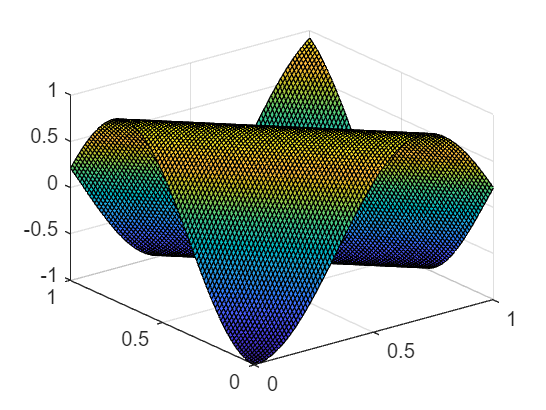

[x, y] = meshgrid(linspace(0, 1, n), linspace(0, 1, n));
xv = x(:);
yv = y(:);
points = [xv, yv].';
Z = reshape(f_Oscillatory(points), [n n]);
surf(x, y, Z)

And the exact integral value

I_ex_osc = exact_ref_solutions('Oscillator', 2);

The Monte Carlo estimate is given by

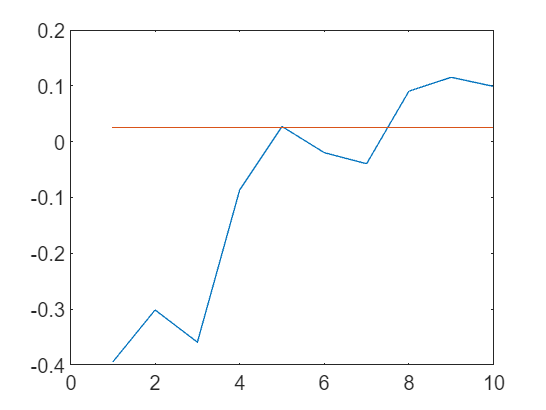

M = 10;
estimates = zeros([1 M]);
for k=1:M
    rng(1)
    estimates(k) = Monte_Carlo_HW1(@f_Oscillatory, 2, k);
end

plot(1:M, estimates, 1:M, I_ex_osc*ones([1 M]))

*2) Product peak function*

The second function is given by the product peak function

                                        
$$f(x) = \prod_{n=1}^N\left(c_n^{-2} + (x_n - w_n)^2\right)^{-1}$$


with $c_n = \frac{7.25}{N}$, $w_n=\frac{1}{2}$ and the exact solution to the corresponding integral is$

                
$$I_{ex} = \prod_{n=1}^Nc_n\left(\arctan(c_n(1-w_n)) + \arctan(c_nw_n)\right)$$


The plot is

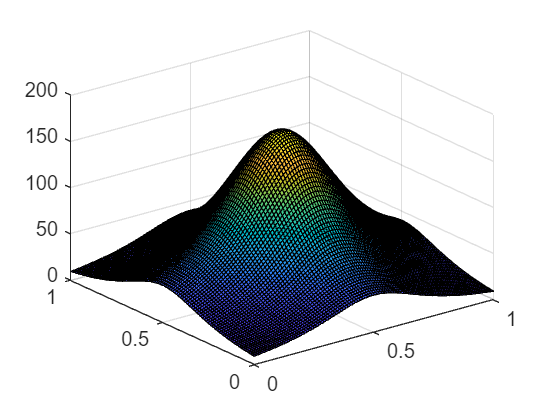

Z = reshape(f_productpeak(points), [n n]);
surf(x, y, Z)

And the exact integral value

I_ex_prodpeak = exact_ref_solutions('Product Peak', 2);

The Monte Carlo estimate is given by

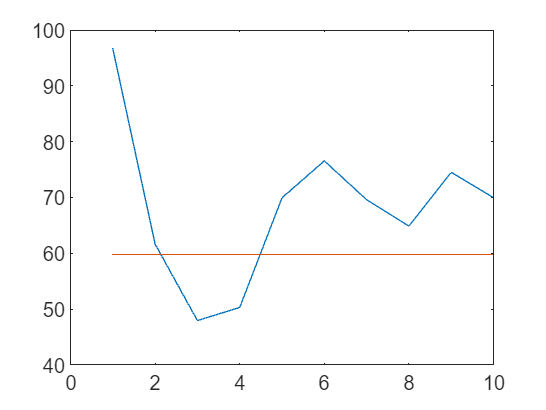

M = 10;
estimates = zeros([1 M]);
for k=1:M
    rng(1)
    estimates(k) = Monte_Carlo_HW1(@f_productpeak, 2, k);
end

plot(1:M, estimates, 1:M, I_ex_prodpeak*ones([1 M]))

*3) Corner peak function*

The third function is given by the corner peak function

                            
$$f(x) = \left(1+\sum_{n=1}^N c_nx_n\right)^{-N+1}$$


with $c_n=\frac{1.85}{N}$ and whose plot is given by

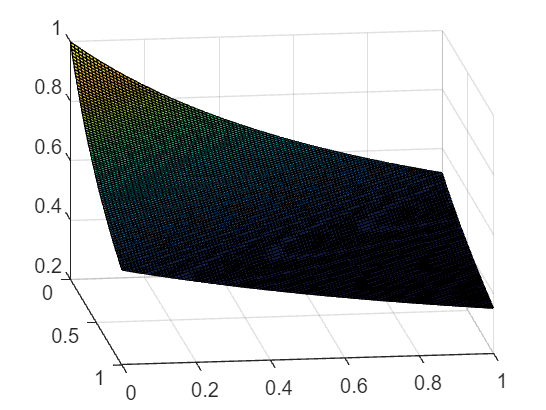

Z = reshape(f_cornerpeak(points), [n n]);
surf(x, y, Z)
view([82.122 19.949])

Since there is no reference solution given in the homework sheet, I will use an approximation

                                    
$$I_{ex} = 0.5415855753$$


for now.

I_ex_cornerpeak = 0.5415855753;

The Monte Carlo estimate is given by

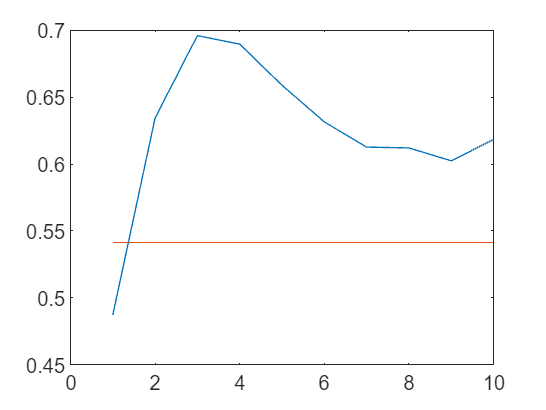

M = 10;
estimates = zeros([1 M]);
for k=1:M
    rng(1)
    estimates(k) = Monte_Carlo_HW1(@f_cornerpeak, 2, k);
end

plot(1:M, estimates, 1:M, I_ex_cornerpeak*ones([1 M]))

*4) Gaussian*

The fourth function is given by a Gaussian function

                              
$$f(x) = \exp\left(-\sum_{n=1}^Nc_n^2(x_n-w_n)^2\right)$$


with $c_n = \frac{7.03}{N}$, $w_n=\frac{1}{2}$ and the exact solution to the integral

                $I_{ex} = \prod_{n=1}^N\frac{\sqrt{\pi}}{2c_n}\left(\text{erf}(c_n(1-w_n)) + \text{erf}(c_nw_n)\right)$.

The plot is given by

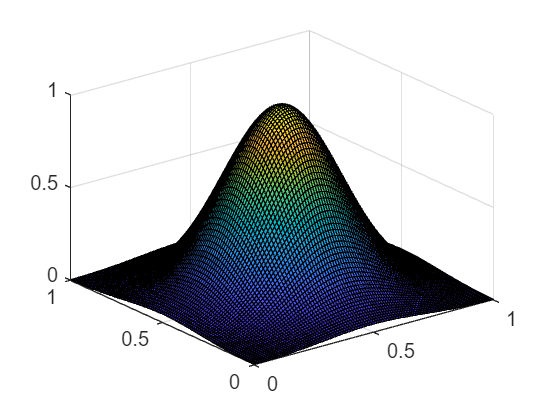

Z = reshape(f_gaussian(points), [n n]);
surf(x, y, Z)

and the exact solution

I_ex_gaussian = exact_ref_solutions("Gaussian", 2);

A Monte Carlo estimate is shown below

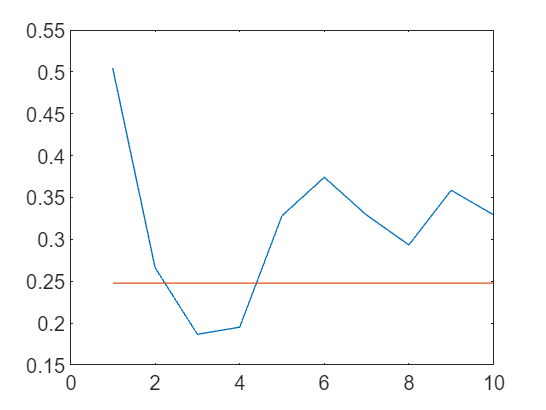

M = 10;
estimates = zeros([1 M]);
for k=1:M
    rng(1)
    estimates(k) = Monte_Carlo_HW1(@f_gaussian, 2, k);
end

plot(1:M, estimates, 1:M, I_ex_gaussian*ones([1 M]))

*5) Continuous*

The fifth function is a continuous function 

                        
$$f(x) = \exp\left(-\sum_{n=1}^Nc_n|x_n-w_n|\right)$$


with  $c_n = \frac{2.04}{N}$, $w_n=\frac{1}{2}$ and exact solution to the integral

                        $I_{ex}=\prod_{n=1}^N\frac{1}{c_n}\left(2 - e^{-c_nw_n} - e^{-c_n(1-w_n)} \right)$.

The plot is

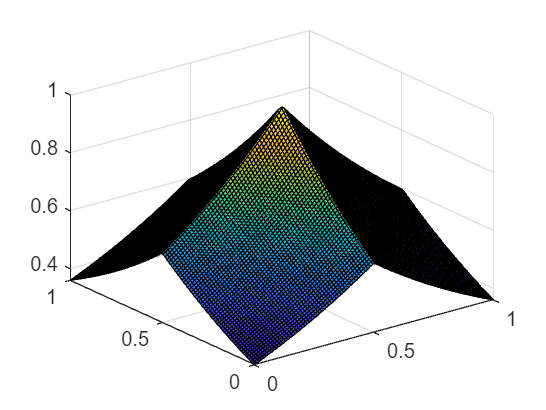

Z = reshape(f_continuous(points), [n n]);
surf(x, y, Z)

and the exact solution

I_ex_continuous = exact_ref_solutions("Continuous", 2);

A Monte Carlo estimate is shown below

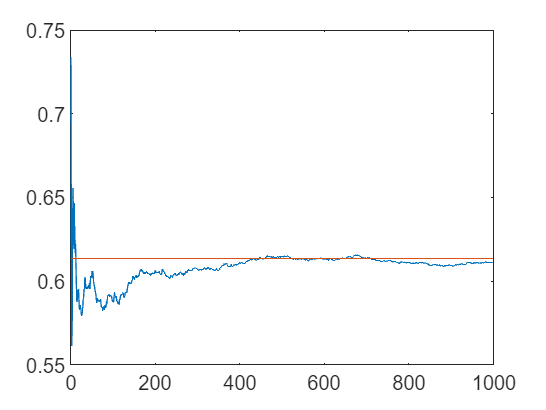

M = 1000;
estimates = zeros([1 M]);
for k=1:M
    rng(1)
    estimates(k) = Monte_Carlo_HW1(@f_continuous, 2, k);
end

plot(1:M, estimates, 1:M, I_ex_continuous*ones([1 M]))

*6) Discontinuous*

The sixth (last) function is given by a discontinuous function


$$f(x) = 0, \quad\text{if}\;x_1>w_1\;\text{or}\;x_2>w_2,\quad f(x) = \exp\left(\sum_{n=1}^N c_nw_n\right),\quad\text{otherwise}
$$


with $c_i=\frac{4.3}{N}$, $w_1=\frac{\pi}{4}$ and $w_2=\frac{\pi}{5}$. The exact solution to the corresponding integral is given by

                        $I_{ex} =\frac{1}{\prod_{n=1}^Nc_n}(e^{c_1w_1}-1)(e^{c_2w_w}-1)\prod_{n=1}^N(e^{c_n}-1)$.

The plot is

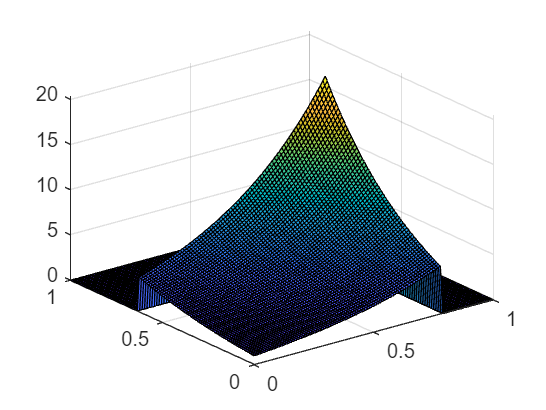

Z = reshape(f_discontinuous(points), [n n]);
surf(x, y, Z, 'FaceColor', 'flat')

The exact solution is

I_ex_discontinuous = exact_ref_solutions("Discontinuous", 2);

A Monte Carlo estimate is given below

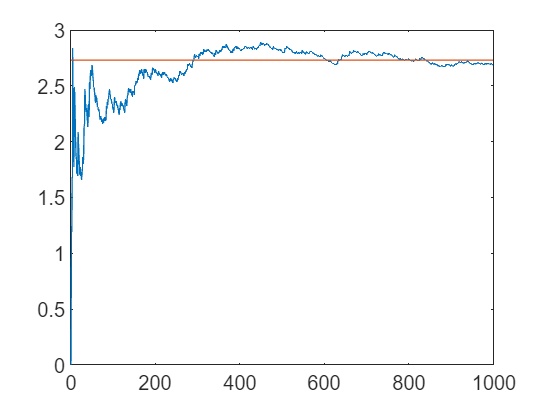

M = 1000;
estimates = zeros([1 M]);
for k=1:M
    rng(1)
    estimates(k) = Monte_Carlo_HW1(@f_discontinuous, 2, k);
end

plot(1:M, estimates, 1:M, I_ex_discontinuous*ones([1 M]))